## Execução com a ERMxSC02 (FSL@ANATEL/SC)

Conectado e respondendo à sua identificação:

disp('Propriedades:')

Propriedades:


callTCP = Analysers.Analyser.connTCP("10.48.10.241", 5025)

callTCP =   dictionary (string ⟼ string) with 6 entries:

    "Factory" ⟼ "Rohde_Schwarz"
    "model"   ⟼ "FSL_6"
    "serial"  ⟼ "100711/006"
    "version" ⟼ "2.30"
    "ip"      ⟼ "10.48.10.241"
    "port"    ⟼ "5025"


obj = Analysers.Analyser.instance(callTCP);

Analyer: Base de comando(Rohde_Schwarz), modelo (FSL_6).


obj.preAmp('On')

Analyer.sendCMD: Criando nova conexão TCP.


obj.setRes(10)
obj.setSpan(500)


% Portadora em 100.9 MHz
obj.setFreq(100900000)

% Obtém o traço
trace = obj.getTrace(1);
disp('Trace:')

Trace:


% Só as 5 primeiras linhas
disp(trace (1:5,:));

      freq        value 
    _________    _______

    1.009e+08    -96.832
    1.009e+08    -94.447
    1.009e+08    -92.004
    1.009e+08    -89.957
    1.009e+08    -88.437



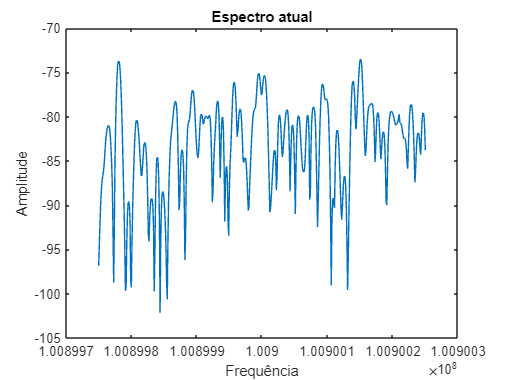


%% Plota o Trace
plot(trace.freq,trace.value,"DisplayName","value");

% Add xlabel, ylabel, title, and legend
xlabel("Frequência")
ylabel("Amplitude")
title("Espectro atual")

legend('off');

disp('Leitura do marcador:')

Leitura do marcador:


nivel = obj.getMarker(100900000, 1);
disp(nivel)

-77.4897842407




% Portadora em 101.7 MHz
obj.setFreq(101700000)

% Obtém o traço
trace = obj.getTrace(1);
disp('Trace:')

Trace:


% Só as 5 primeiras linhas
disp(trace (1:5,:));

      freq        value 
    _________    _______

    1.017e+08    -86.676
    1.017e+08    -94.553
    1.017e+08    -90.846
    1.017e+08    -86.377
    1.017e+08    -84.688




%% Plota o Trace
p = plot(trace.freq,trace.value,"DisplayName","value");

% Add xlabel, ylabel, title, and legend
xlabel("Frequência")
ylabel("Amplitude")
title("Espectro atual")
legend('off');

disp('Leitura do marcador:')

Leitura do marcador:


nivel = obj.getMarker(101700000, 1);
disp(nivel)

-77.4897842407



disp("As duas maiores emissoras da região estão com nível muito baixo.")

As duas maiores emissoras da região estão com nível muito baixo.



% trcs = fcn.getTracesFromUnit(obj, 1000);

% Encerra ativamente a conexão
obj.disconnect()

disp("Pronto")